clear;
close all;
clc;
initime = clock;
% func_path = fullfile('..', 'funcs');
addpath('../funcs');
% addpath(func_path);

Delta_e = 0.2;
Delta_i = 0.02;
Iattn = 0.02;
allTime = 4000;
[r,v,g] = once(Delta_e, Delta_i, Iattn, allTime);
r = r*1000;
PET = getPET(v,g);

## firing rates by layers, E/I, 5 conds

env = getEnvelope(r);

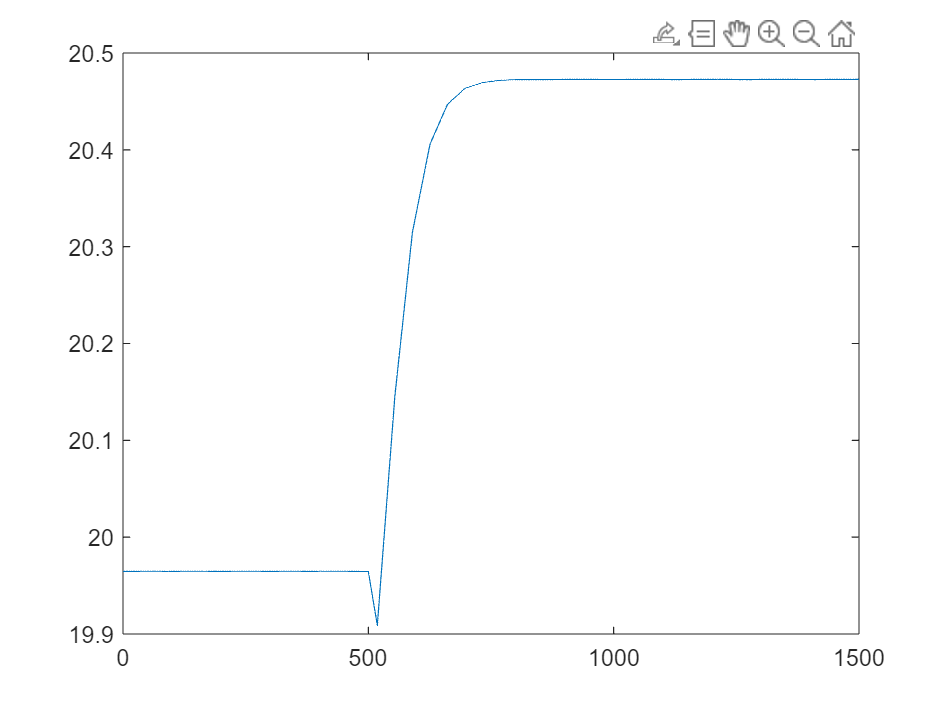

figure();
% 500 + 1000*5 = 5500
timeax = 0:0.01:5500;
% plot L2/3 in red #EA4335
L23E = plot(timeax(1:150000), env(1,50001:200000,1));


% plot L4 in yellow #FBBC05


% plot L5 in blue #4285F4


% plot L6 in green #34A853



## firing rates by layers, E +/- I, 5 cons